**Clear Functions**

clear;
close all;
clc;

**Initial Conditions**

rE = 6378; % Radius of Earth (km)
mu = 3.986e5; %mu for Earth
we = (2*pi + 2*pi/365.26)/(24*3600); % Earths Angular Velocity (rad/s)

% Inital position and velocity vectors

r0 = [-22680.21 -13923.69 92.92];
v0 = [0 0 sqrt(mu/norm(r0))];


**Convert from ECIF to ECEF**

utc = [2000 1 1 12 0 0];
[r_ecef,v_ecef] = eci2ecef(utc,r0,v0);

% Qxx = [cosd(omega), sind(omega), 0;
%     -sind(omega), cosd(omega), 0;
%     0, 0, 1];

% Convert the original matrices to vertial
% r0 = r0.';
% v0 = v0.';

% Calculate final state vector in ECEF
% rX = Qxx*r0;
% vX = Qxx*v0;

**Calculating Orbital Elements**

r = norm(r_ecef); % Calc distance
v = norm(v_ecef); % Calc speed
vR = (r_ecef(1)*v_ecef(1) + r_ecef(2)*v_ecef(2) + r_ecef(3)*v_ecef(3))/r; %Radial velocity
hV = cross(r_ecef,v_ecef); % Vector specific angular momentum
h = norm(hV); % Magnitude of specific angular momentum

i = acosd(hV(3)/h); % Inclination
% Node line
K = [0,0,1];
NV = cross(K,hV); % Node line vector
N = norm(NV); % Magnitude of node line


omegaRA = acosd(NV(1)/N); % Right Ascension (RA) of ascending node

if NV(2) < 0
    omegaRA = 360-omegaRA;
end


% Calculate eccentricity vector
eV = 1/mu*((v^2-mu/r)*r_ecef-r*vR*v_ecef);
e = norm(eV); % Magnitude of eccentricity vector

omega = acosd(dot(NV,eV)/(N*e)); % Argument of perigee

theta = acosd(dot(eV,r_ecef)/(e*r)); % True Anomaly

rp = (h^2/mu)*(1/(1+e*cosd(0))); % Perigee radii
ra = (h^2/mu)*(1/(1+e*cosd(180))); % apogee radii


a = 1/2*(rp+ra); % Semimajor axis (km)
T = (2*pi)*sqrt(a^3/mu);

% R1 = [ cos(W) sin(W) 0
%         -sin(W) cos(W) 0
%         0 0 1];
% R2 = [1 0 0
%         0 cos(incl) sin(incl)
%         0 -sin(incl) cos(incl)];
% R3 = [ cos(wp) sin(wp) 0
%         -sin(wp) cos(wp) 0
%         0 0 1];
% QxX = (R3*R2*R1)’;



**State Vector and Timespans**

s0 = [r_ecef;v_ecef];


timeSpan = 0:3*T;

**Call ODE45 Function**

*Note going to call multiple times for multiple orbits on same ECIF frame*

Inputs:* t, s, *$\mu$

Output: $\overrightarrow{\textrm{sol}}$

[~, sol] = ode45(@(t,s)diffEq(t,s,mu), timeSpan, s0); 

**Convert to Latitude and Longitude**

latlong = ecef2lla(sol(:,1:3));

**Figure Configuration**

figure;

hold on; grid on; grid minor; axis equal; 
xlabel('East Longitude (degrees)')
ylabel('Latitude (degrees)')

title('One GEO Orbits in ECEF');

**Plotting Groundtracks**

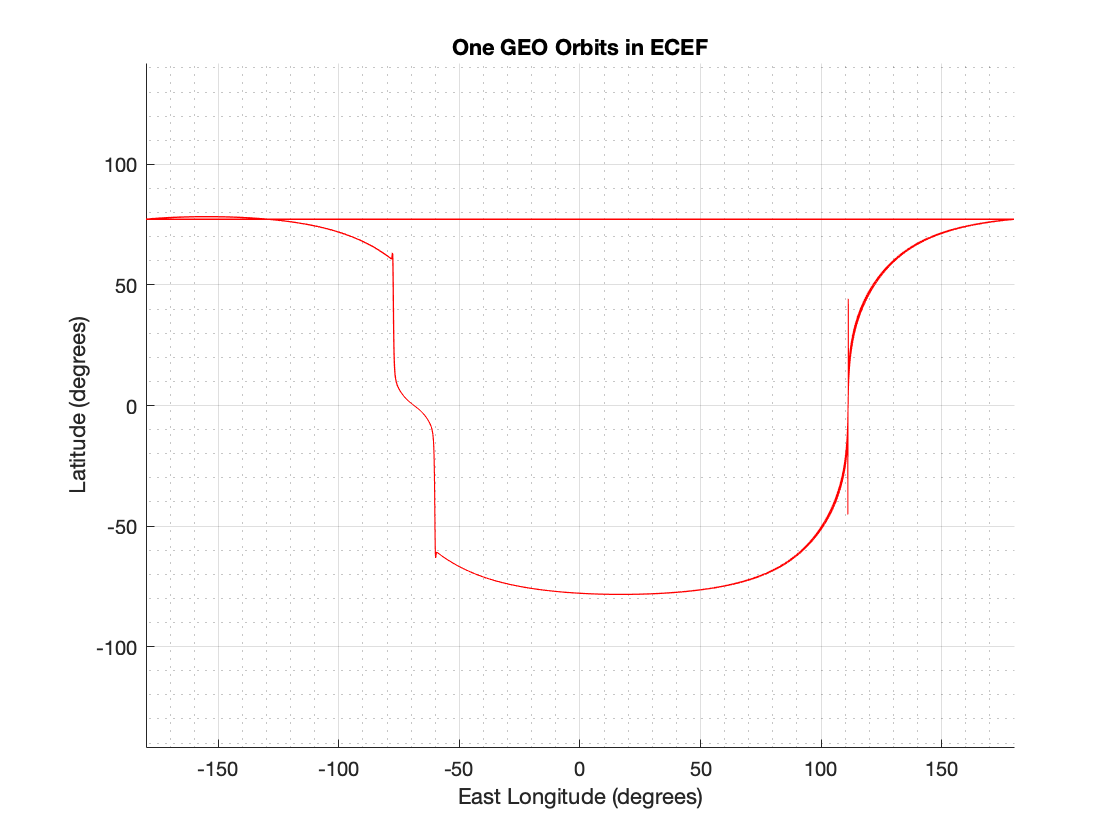



plot(latlong(:,2), latlong(:,1), '-r');

**ODE45 Function**

function sdot = diffEq(t,s,mu)

% r is first three elements, v is last three
rDQ = s(1:3);
vDQ = s(4:6);

sdot(1:3,1) = vDQ; %First three elements are velocity
sdot(4:6,1) = (-mu*rDQ)/(norm(rDQ))^3; % Actual two body EOM


end

